# Q1

(a)

Given a linear equation $Ax=b$


$$A=UDV$$


then we can calculated the MP-inverse of $A$, i.e. $A^+=VPU^H$, hence the solution (if it has) is $A^+b$

Here $P$ is a diagonal matrix with 

$P_{ii}=\frac{1}{D_{ii}}$ if $D_{ii}\neq 0$, $P_{ii} =0$ otherwise (within tolerance)

(b) See tail of the file.

I will choose less sensitive one. Since the given data is not uniform and the whold shape depends heavily on the given points.

# Q2

from $U,V,\Sigma$ we can see 

- rank(A) = 2

- numerical rank(A) = 1 since $\Sigma$ has $2.803\times10^{-5}<\epsilon_{macch}$

- 
$$||A||_2\approx 7.979+2.803\times 10^{-5}\approx 7.9793$$


- cond(A) $\approx 2.8466\times10^5$

- take the largest singular value $7.979$ at $k=1$, then the rank one approximation of A is $\sigma_1 u_1 v_1^T$, which is $\left\lbrack \begin{array}{cc}
1\ldotp 0002 & -3\ldotp 1005\\
2\ldotp 0001 & -6\ldotp 2002\\
-1\ldotp 0002 & 3\ldotp 1005
\end{array}\right\rbrack$.

- this approximate $A$ well since the other sigular is much smaller than the largest singular value. The rank-one approximation extracts the main  component of $A$.

U = [
    [4.083e-1, 1.826e-1, 8.944e-1];
    [8.165e-1, 3.652e-1, -4.472e-1];
    [-4.083e-1, 9.129e-1, 6.170e-12]
];
V = [
    [3.070e-1, 9.517e-1];
    [-9.517e-1, 3.070e-1]
];
S = [
    [7.979, 0];
    [0, 2.803e-5];
    [0,0]
    ]

S =     7.9790         0
         0    0.0000
         0         0


S;
K=U*S*V'

K =     1.0002   -3.1005
    2.0001   -6.2002
   -1.0001    3.1005


norm(K, 2)

ans = 7.9793

cond(K, 2)

ans = 2.8466e+05


Sp = S;
Sp(2,2)=0;
U*Sp*V'

ans =     1.0002   -3.1005
    2.0001   -6.2002
   -1.0002    3.1005


# Q3. Ex 4.10

A = [
    [2, 3, 5, 6];
    [3, -1, -2, -3];
    [5, -2, 0, 2];
    [6, -3, 2, 22]
];

Iteration

err = 1e-6;
x0 = [1, 1, 1, 1]'

x0 =      1
     1
     1
     1


lm0 = inf;

steps = [];

while true
    x1 = A * x0;
    lm1 = max(abs(x1));
    if sum(lm1 >= x1) < 1
        lm1 = -lm1;
    end
    x1 = x1 ./ lm1;
    if max(x0 - x1) < err && abs(lm0 - lm1) < err
        steps = [steps; lm1];
        break;
    end
    x0 = x1;
    lm0 = lm1;
    steps = [steps; lm0];
end

disp("Max Eigenvalue: " + lm1)

Max Eigenvalue: 24.3235


disp("Max Eigenvector: ")

Max Eigenvector: 


disp(x1)

    0.2894
   -0.0960
    0.1496
    1.0000



Compare with eig

[V, D] = eig(A);

evals = diag(D);
mx = evals(4);

ads = steps - mx;
ads = (ads(2:end) - mx) ./ (ads(1:end-1) - mx)

ads =     1.0342
    1.0857
    0.9966
    1.0045
    0.9994
    1.0003
    0.9999
    1.0000
    1.0000
    1.0000


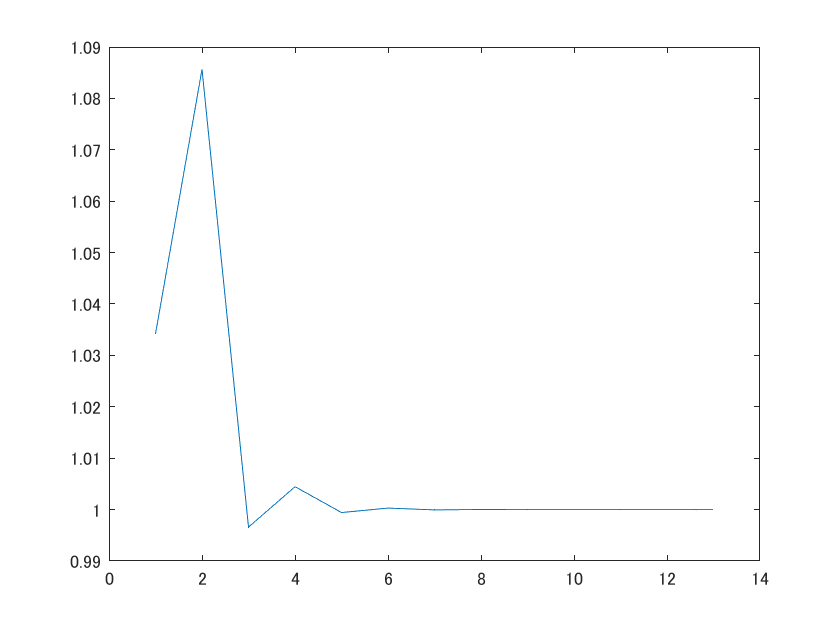


xs = 1 : length(ads);
ys = ads;

figure;
plot(xs, ys);

Hence the convergence rate is about $1.0$.

# Q4


$$\left\lbrack \begin{array}{cccc}
3 & 1 & 0 & 0\\
1 & -1 & 2 & 0\\
0 & 2 & 1 & 1\\
0 & 0 & 1 & 1
\end{array}\right\rbrack =A$$


(a) 


$$R_1=1,\ a_{11}=3$$



$$R_2=1+2=3,\ a_{22}=-1$$



$$R_3=2+1=3,\ a_{33}=1$$



$$R_4=1,\ a_{44}=1$$


Note that $A$ is ysmmetric, hence every eigenvalue of $A$ lies in at least one of the discs $D(a_{ii},R_i)$, $i=1,2,3,4$

Region: $\cup D(a_{ii},R_i)$

Eigenvalues cannot be anywhere in the region, since $A$ is symmetric matrix, its eigenvalues must be all real, hence eigenvalues must lay on the real axis of the complex plane and cannot contain imaginary component.

(b) See the tail of this file

(c) 

A = [
    [3, 1, 0, 0];
    [1, -1, 2, 0];
    [0, 2, 1, 1];
    [0, 0, 1, 1]
];
U = eig(A)

U =    -2.4495
    0.5858
    2.4495
    3.4142


a1 = sturm(A, -5)

a1 = 4

a2 = sturm(A, 5)

a2 = 0

a3 = sturm(A, 0)

a3 = 3

a4 = sturm(A, 2.5)

a4 = 1

a5 = sturm(A, 1.25)

a5 = 2

Hence each of the intervals 

- $[-5,0]$, $[0,1.25],[1.25,2.5],[2.5,5]$

contains one eigen value, this conforms with the result we get from `eig`.

(b) function

function num = sturm(A, t)
    n = length(A(:, 1));
    ps = zeros(n + 1);
    
    ps(1) = 1;
    if n > 1
        ps(2) = A(1, 1) - t;
    end
    if n > 2
        ps(3) = (A(2, 2) - t) * (A(1, 1) - t) - A(2, 1) ^ 2;
    end
    for k = 4 : (n + 1)
        ps(k) = (A(k - 1, k - 1) - t) * ps(k - 1) - A(k - 1, k - 2) ^ 2 * ps(k - 2);
    end
    
    num = 0;
    for i = 2 : n + 1
        if ps(i) * ps(i - 1) > 0 || ps(i) == 0
            num = num + 1;
        end
    end
end

Q1. (b)

function x = svd_solve(A, b, err)
    [U, S, V] = svd(A);
    m = (length(A(:, 1)));
    n = length(A(1, :));
    s = min(m, n);
    Sig = zeros(s, s);
    for i = 1 : s
        if abs(S(i, i)) < err
            Sig(i, i) = 0;
        else
            Sig(i, i) = 1 / S(i, i);
        end
    end
    x = V * Sig * U' * b;
end